# Signal Processing for a stationary signal

Author: Vishu Sharma

Description: Code to calculate  FFT of a stationary signal

Last Modified: 09.10.2021

clear all, clc

fs = 500; % Sampling frequency
T = 1/fs; % Sampling period
L = 2000; % length of signal
t = (0: L-1)*T;
w=2*pi;

Signal and Noise

A = 10*sin(15*w*t);
B = 7*sin(30*w*t);
C = 5*sin(50*w*t);
D = 3*cos(100*w*t);

N = 0.5*rand(size(t));
Res_y = A+B+C+D+N;

Signal in time domain

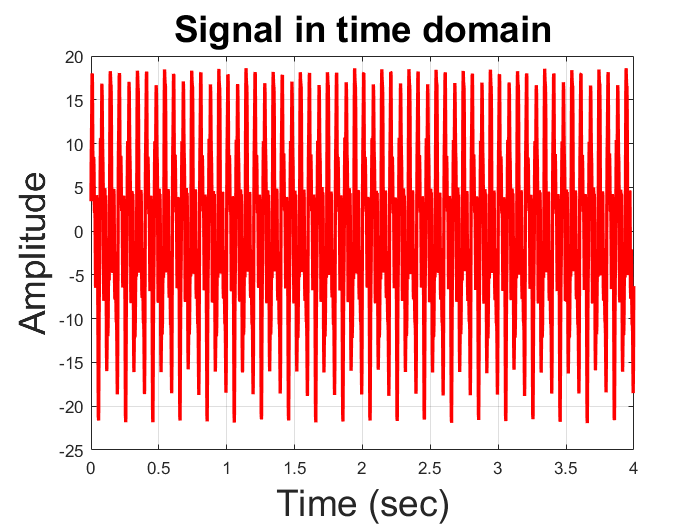

plot(t,Res_y, 'r','LineWidth',2)
grid on
title('Signal in time domain','FontSize', 22)
xlabel('Time (sec)', 'FontSize', 22)
ylabel('Amplitude','FontSize', 22)

Fourier Spectral Analysis

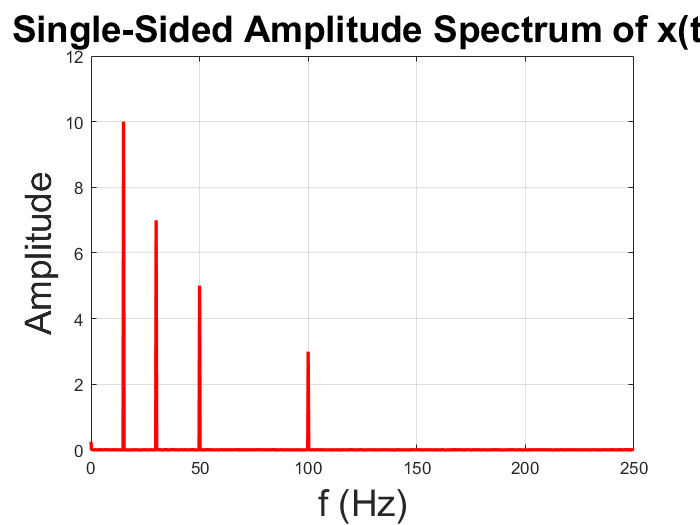

Y = fft(Res_y);

P2 = abs(Y/L);     % double sided spectrum
P1 = P2(1:L/2+1);  % single sided spectrum
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(L/2))/L;
plot(f,P1, 'r', 'LineWidth',2) 
title('Single-Sided Amplitude Spectrum of x(t)','FontSize', 22)
xlabel('f (Hz)','FontSize', 22)
ylabel('Amplitude','FontSize', 22)
grid on